clc
clear
a=[-1 -1 ;6.5 0]; %定义系统的状态空间模型系数
b=[1 1; 1 0];
c=[1 1; 1 0];
d=[0 0; 0 0];
[num,den] = ss2tf(a,b,c,d,1); %将状态空间模型转换为传递函数模型
[num2,den2] = ss2tf(a,b,c,d,2); %将状态空间模型转换为传递函数模型
hold on; %打开绘图开关
t=0:0.01:10; %定义时间变量t
step(a,b,c,d,1,t); %绘制输入1的单位阶跃响应
step(a,b,c,d,2,t); %绘制输入2的单位阶跃响应
sysabcd=ss(a,b,c,d); %系统封装
step(sysabcd); %绘制系统的单位阶跃响应 


num=[1.9691 5.0395]; %定义传递函数分子系数
den=[1 0.5572 0.6106]; %定义传递函数分母系数
t=0:0.01:10; %响应时间
subplot(1,2,1);impulse(num,den,t) 
grid %在绘制的图形中添加栅格
u=sin(2.*t) %输入为正弦信号
subplot(1,2,2);lsim(num,den,u,t) 
grid %添加栅格

num=[1 10];den=[1 6 9 10]; %定义系统传递函数的系数
t=0:0.1:12; %定义时间变量t
r=exp(-0.5*t); %定义输入信号
y=lsim(num,den,r,t); %定义输入为r的响应曲线y
plot(t,r,'-',t,y,'o'); %绘制输入输出曲线
grid; %在绘制的图形中添加栅格
title('Rrsponse to Input r=e^{-0.5t}'); %添加标题
xlabel('t sec','FontSize',8); %标记横坐标
ylabel('Input and Output','FontSize',8); %标记纵坐标
legend('Input','output'); %对曲线添加标注
text(1.0,0.85,'Input r=e^{-0.5t}');
text(4.1,0.35,'Output');

clear;zeta=0.25;wn=2; %定义系统阻尼比和振荡角频率
addpath Function/
num=[wn^2]; %定义传递函数分子系数
den=[1,2*zeta*wn,wn^2]; %定义传递函数分母系数
sys=tf(num,den); %建立传递函数模型
t=[0:0.01:20]; %响应时间
[Y,T]=step(sys,t); %单位阶跃响应
[mp, tp, sigma,tr1,tr2,ts]=steppa(Y,T) %调用自行设计的steppah函数

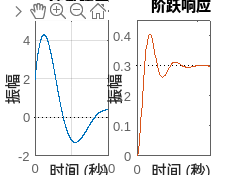

clear
clc
z=[];p=[-1+3i,-1-3i];k=3; %系统的零点向量、极点向量和增益
syszpk=zpk(z,p,k); %建立零极点函数模型
step(syszpk) %单位阶跃响应曲线